clearvars;
addpath("RIR/");

### Initial parameter

c = 340;                    % Sound velocity (m/s)
fs = 44100;                 % Sample frequency (samples/s)
r = [1 1 1];              % Receiver position [x y z] (m)
s = [5 5 5];              % Source position [x y z] (m)
L = [10 10 10];                % Room dimensions [x y z] (m)
alpha = 1;
beta = sqrt(1-alpha);                % Reverberation time (s)
n = 10000;                   % Number of samples
t = (1:n)/44100;

### LMS using RIR

As the previous atempt has failed, because the implementation of the image source method was useless, we will try implementing the Least Mean Square algorithm with a different implementation of the IMS.

First we test the ISM implementation.

#### Testing RIR

h = rir_generator(c, fs, r, s, L, beta, n);

Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.
1.000000


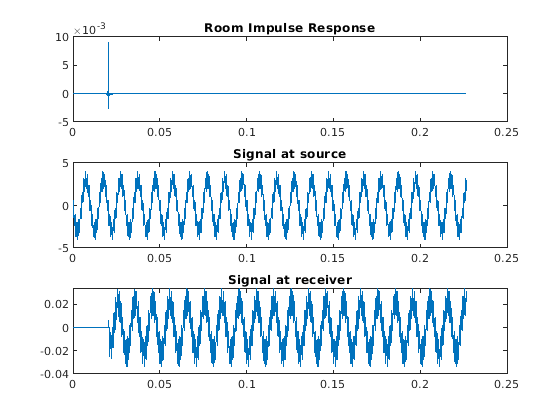

subplot(311);
plot(t,h);
title("Room Impulse Response");
subplot(312);
signal = sin(2*pi*1000*t) + 3*sin(2*pi*100*t + pi);
plot(t,signal);
title("Signal at source");
subplot(313);
ims_sig = conv(signal,h);
plot(t,ims_sig(1:n));
title("Signal at receiver");

The implementations seems to work, but its validity needs to be tested.

#### LMS

The lms implemented below expects the secondary source as well as the primary source directly at the error microphone.

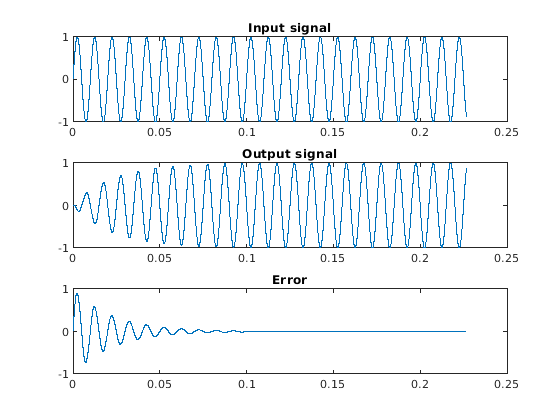

x = 1*sin(2*pi*100*t);
mu = 0.001; % Step size
M=1; % Length of signal fragment used for computation at each step

N=length(t);
%inital values: 0
w=zeros(1,M);
y = zeros(1,N);
e = zeros(1,N);
%number of samples of the input signal

%LMS
for i=M:N
    y(i) = w*x(i-M+1:1:i)';
    e(i)=x(i)+y(i);
    w = w-2*mu*e(i)*x(i-M+1:1:i);
end
ee = x + y;

figure;
subplot(311);
plot(t,x);
title("Input signal");
subplot(312);
plot(t,y);
title("Output signal");
subplot(313);
plot(t,ee);
title("Error");

#### Noise signal at error microphone

The noise signal reaching the error microphone needs to be calculated only once using image source implementation

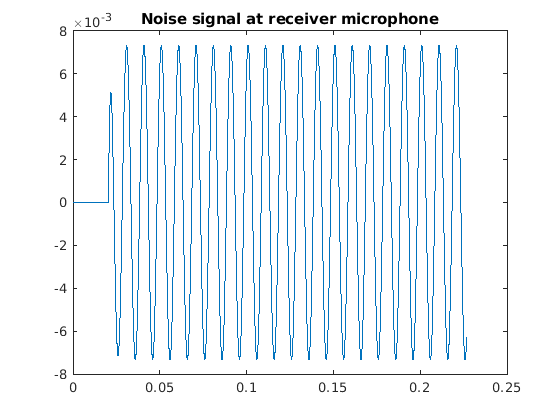

x_ism = conv(x,h);
x_ism = x_ism(1:n);
figure;
plot(t,x_ism);
title("Noise signal at receiver microphone");

#### Secondary source signal at error microphone

The secondary noise signal at the receiver needs to be computed with each loop iteration of the least mean square algorithm.

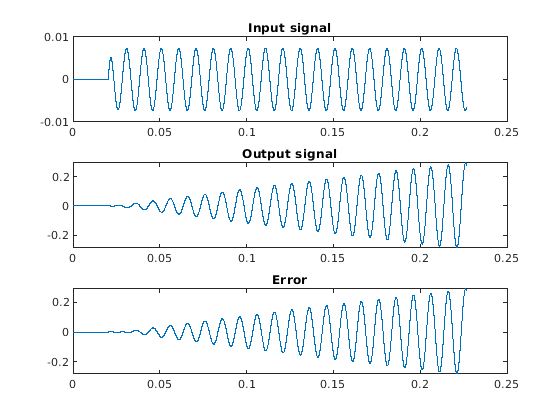

N=length(t);
%inital values: 0
y = zeros(1,N);
e = zeros(1,N);
%number of samples of the input signal
mu = 1; % Step size
M=200; % Length of signal fragment used for computation at each step
w=zeros(1,M);


%LMS
for i=M:N
    y(i) = w*x_ism(i-M+1:1:i)';
    y_ism = conv(y,h);
    y_ism = y_ism(1:n);
    e = x_ism + y_ism;
    w = w-2*mu*e(i)*x_ism(i-M+1:1:i);
end
ee = x_ism + y;

figure;
subplot(311);
plot(t,x_ism);
title("Input signal");
subplot(312);
plot(t,y);
title("Output signal");
subplot(313);
plot(t,ee);
title("Error");